## **Worked Example 2.2**

 AERO60007 Control Systems 2024-2025

% Housekeeping
clear
clc
close all

% Input the dynamics matrix
A = [1, 3; 3, -6];

% Calculate the characteristic polynomial
% This function will produce a vector of the polynomial coefficients
% corresponding to the 𝑥^2, 𝑥 and constant terms respectively
p = poly(A)

p =     1.0000    5.0000  -15.0000


% Calculate the open-loop eigenvalues
lambda = eig(A)

lambda =    -7.1098
    2.1098


% Input the B, C and D matrices and create a state-space system
B = [1; 0];
C = [1, 0];
D = 0;
sys = ss(A, B, C, D);

% Convert the dynamics matrix to its modal form
A_m = canon(sys, 'modal')


A_m =
 
  A = 
          x1     x2
   x1   2.11      0
   x2      0  -7.11
 
  B = 
            u1
   x1   0.9379
   x2  -0.3469
 
  C = 
            x1       x2
   y1   0.9379  -0.3469
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.


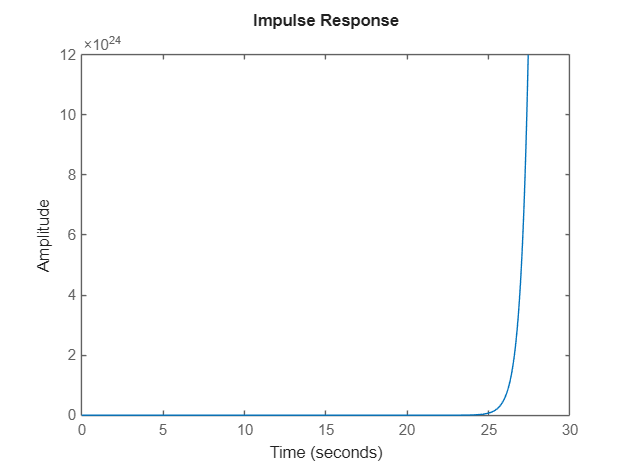


% Plot the impulse response of the system
impulse(sys)

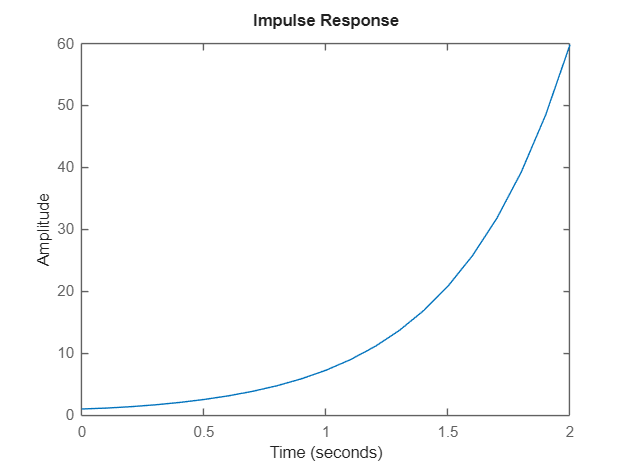


T = [0 : 0.1 : 2];
impulse(sys, T)

% Declare the algebraic feedback gain variable k
syms k

% Construct the closed-loop dynamics matrix
A_cl = A + B * k * C

$$A\_cl = \left(\begin{array}{cc} k+1 & 3\\ 3 & -6 \end{array}\right)$$


% Find the closed-loop characteristic polynomia
P_cl = charpoly(A_cl)

$$P\_cl = \left(\begin{array}{ccc} 1 & 5-k & -6\,k-15 \end{array}\right)$$

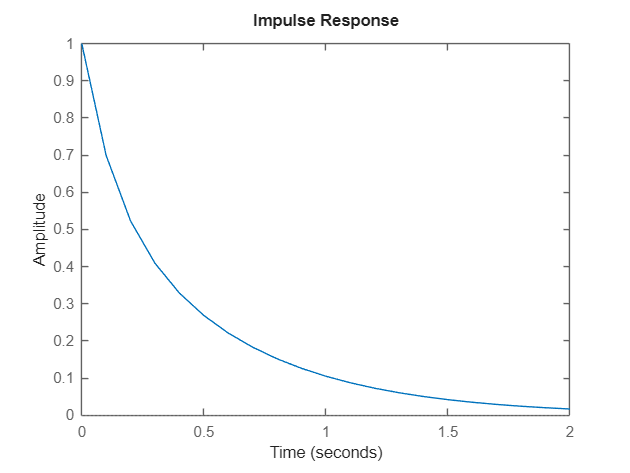

% for k = -5
k = -5;

A_cl = A + B * k * C;

sys1 = ss(A_cl, B, C, D); % B for external input, e.g. impulse

impulse(sys1, T)